### Benjamin Rosenberg    EECE 5644    Take Home Exam 1

# Question 1

Data set generation:

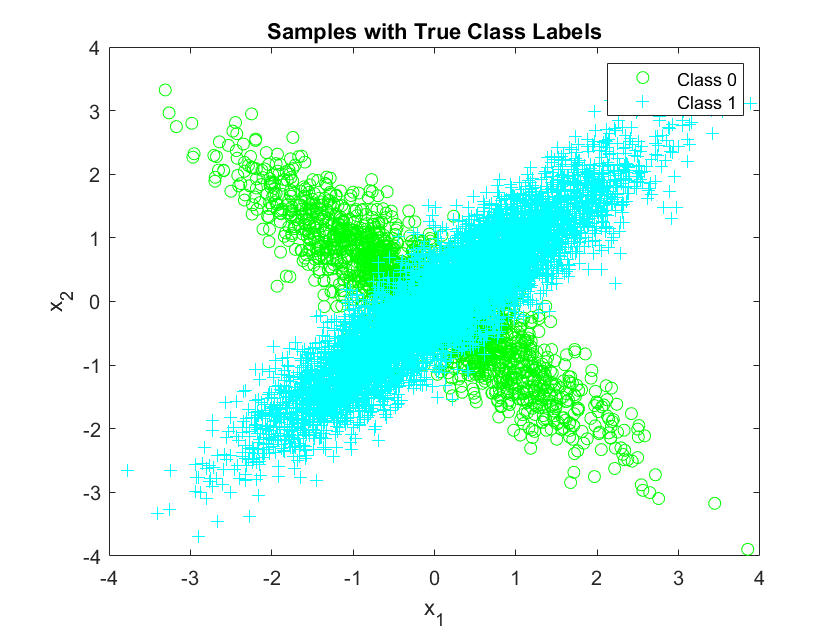

% Create both classes as structs
class0.label = 0;
class0.prior = 0.8;
class0.mu = [-0.1;0];
class0.sigma = [1 -0.9;-0.9 1];

class1.label = 1;
class1.prior = 0.2;
class1.mu = [0.1;0];
class1.sigma = [1 0.9;0.9 1];

% Create data labels
labels = rand(1,10000);
% Assign pdfs to samples, given labels
for ii = 1:length(labels)
    if labels(ii) >= class0.prior
        samples(ii).value = mvnrnd(class0.mu, class0.sigma)';
        samples(ii).label = 0;
    else
        samples(ii).value = mvnrnd(class1.mu, class1.sigma)';
        samples(ii).label = 1;
    end
end

% Parse out points for plotting
samples0 = [samples([samples.label] == 0).value];
samples0x = [samples0(1:2:end)];
samples0y = [samples0(2:2:end)];

samples1 = [samples([samples.label] == 1).value];
samples1x = [samples1(1:2:end)];
samples1y = [samples1(2:2:end)];

plot(samples0x,samples0y,'go');
xlabel('x_1');ylabel('x_2');
title('Samples with True Class Labels');
hold on;
plot(samples1x,samples1y,'c+');
hold off;
legend('Class 0', 'Class 1');

1. For two-label classification, conditional risk is given as: $R(\alpha_0)=\lambda_{00}P(L=0|\mathbf{x})+ \lambda_{01}P(L=1|\mathbf{x})\\
R(\alpha_1)=\lambda_{10}P(L=0|\mathbf{x})+ \lambda_{11}P(L=1|\mathbf{x})
$,

where $\lambda_{ij}$is a fixed loss value for $D=i|L=j$, and$P(L=i|\mathbf{x})$is the posterior probability of class *i. *In order to minimize expected risk:

$(\lambda_{10}-\lambda_{00})P(L=0|\mathbf{x}) {<} (\lambda_{01}-\lambda_{11})P(L=1|\mathbf{x}) \Longrightarrow D=1$, which can be rewritten using Bayes rule as$(\lambda_{10}-\lambda_{00})P(\mathbf{x}|L=0)P(L=0) {<} (\lambda_{01}-\lambda_{11})P(\mathbf{x}|L=1)P(L=1) \Longrightarrow D=1$. If we assume $\lambda_{01} > \lambda_{11}$, 

$$\frac{p(\mathbf{x}|L=1)}{p(\mathbf{x}|L=0)}{>}\frac{(\lambda_{10}-\lambda_{00})}{(\lambda_{01}-\lambda_{11})}\frac{P(L=0)}{P(L=1)}\Longrightarrow D=1$ or $$\frac{p(\mathbf{x}|L=1)}{p(\mathbf{x}|L=0)}{>}\gamma$, where $\gamma = \frac{(\lambda_{10}-\lambda_{00})}{(\lambda_{01}-\lambda_{11})}\frac{P(L=0)}{P(L=1)}$

2. Minimum expected risk classifier implementation on 10,000 samples

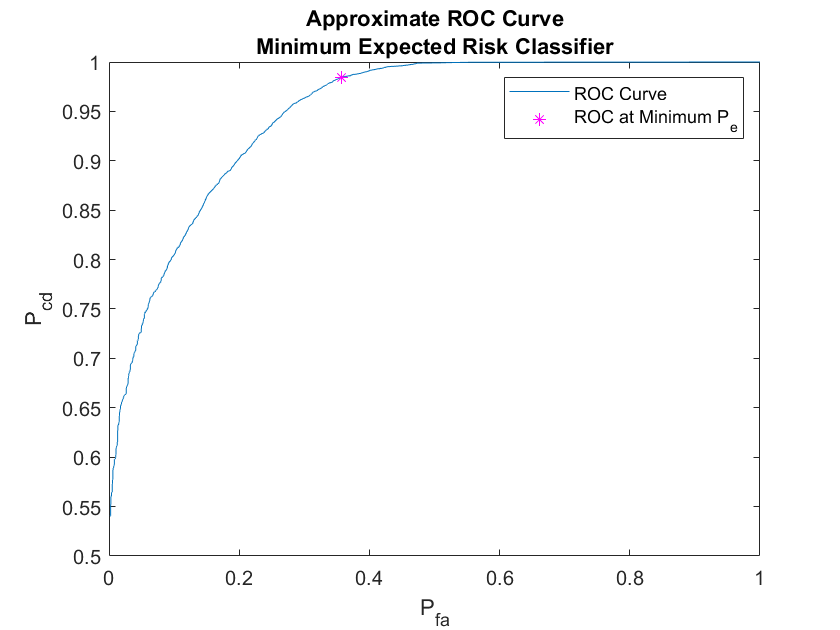

likelihood0 = evalGaussian([samples.value],class0.mu,class0.sigma);
likelihood1 = evalGaussian([samples.value],class1.mu,class1.sigma);
llrt = log(likelihood1) - log(likelihood0);

gamma = 0:0.01:20;
pcd = zeros(1,length(gamma));
pfa = zeros(1,length(gamma));
pe = zeros(1,length(gamma));
for ii = 1:length(gamma)
    decision = double(llrt >= log(gamma(ii)));
    pcd(ii) = sum(decision == 1 & [samples.label] == 1)/sum([samples.label] == 1);
    pfa(ii) = sum(decision == 1 & [samples.label] == 0)/sum([samples.label] == 0);
    pe(ii) = sum(decision ~= [samples.label])/length(samples);
end
% Get the minimum Pe
[val,idx] = min(pe);
% ROC Curve Plot
plot(pfa,pcd); hold on;
xlabel('P_{fa}'); ylabel('P_{cd}'); title({'Approximate ROC Curve','Minimum Expected Risk Classifier'});
plot(pfa(idx),pcd(idx), 'm*'); hold off;
legend('ROC Curve','ROC at Minimum P_e');

3. Threshold value for minimum probability of error, and the respective probability of error at that threshold:

fprintf(['Minimum probability of error: %f\n',...
    'Gamma (threshold) value: %f\nProbability of false alarm: %f \n',...
    'Probability of correct detection: %f'], val,gamma(idx),pfa(idx),pcd(idx));

Minimum probability of error: 0.085200
Gamma (threshold) value: 0.250000
Probability of false alarm: 0.356688 
Probability of correct detection: 0.984420

#### Naive Bayesian Classifier

1. As in the above section for the true covariance matrices:

$$\frac{p_{NB}(\mathbf{x}|L=1)}{p_{NB}(\mathbf{x}|L=0)}{>}\frac{(\lambda_{10}-\lambda_{00})}{(\lambda_{01}-\lambda_{11})}\frac{P(L=0)}{P(L=1)}\Longrightarrow D=1$ or $$\frac{p_{NB}(\mathbf{x}|L=1)}{p_{NB}(\mathbf{x}|L=0)}{>}\gamma$, where $\gamma = \frac{(\lambda_{10}-\lambda_{00})}{(\lambda_{01}-\lambda_{11})}\frac{P_{NB}(L=0)}{P_{NB}(L=1)}$

2. Naive-Bayesian minimum expected risk classifier implementation:

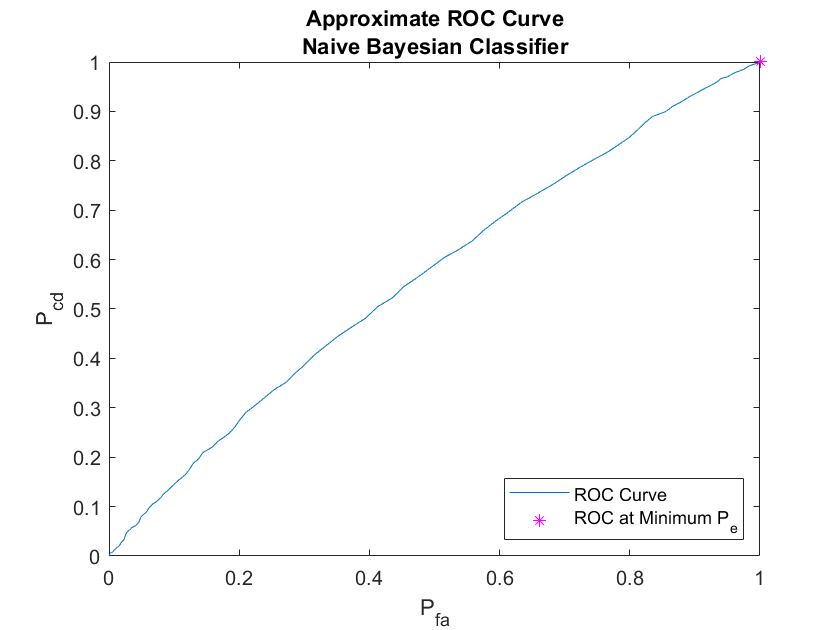

% Assume uncorrelated => Cov = I
likelihood0 = evalGaussian([samples.value],class0.mu,[1 0;0 1]);
likelihood1 = evalGaussian([samples.value],class1.mu,[1 0;0 1]);
llrt = log(likelihood1) - log(likelihood0);

gamma = 0:0.01:20;
pcd = zeros(1,length(gamma));
pfa = zeros(1,length(gamma));
pe = zeros(1,length(gamma));
for ii = 1:length(gamma)
    decision = double(llrt >= log(gamma(ii)));
    pcd(ii) = sum(decision == 1 & [samples.label] == 1)/sum([samples.label] == 1);
    pfa(ii) = sum(decision == 1 & [samples.label] == 0)/sum([samples.label] == 0);
    pe(ii) = sum(decision ~= [samples.label])/length(samples);
end
% Get the minimum Pe
[val,idx] = min(pe);
% ROC Curve Plot
plot(pfa,pcd); hold on;
xlabel('P_{fa}'); ylabel('P_{cd}'); title({'Approximate ROC Curve','Naive Bayesian Classifier'});
plot(pfa(idx),pcd(idx), 'm*'); hold off;
legend('ROC Curve','ROC at Minimum P_e','location','southeast');

3. Threshold value for minimum probability of error, and the respective probability of error at that threshold:

fprintf(['Minimum probability of error: %f\n',...
    'Gamma (threshold) value: %f\nProbability of false alarm: %f \n',...
    'Probability of correct detection: %f'], val,gamma(idx),pfa(idx),pcd(idx));

Minimum probability of error: 0.204100
Gamma (threshold) value: 0.000000
Probability of false alarm: 1.000000 
Probability of correct detection: 1.000000

#### Fisher Linear Discriminant Analysis Classifier

1. The decision rule for a Fisher LDA classifier is $\mathbf{w}^{T}_{LDA}\mathbf{x}>\tau \Longrightarrow D=1$

2. Fisher LDA classifier implementation:

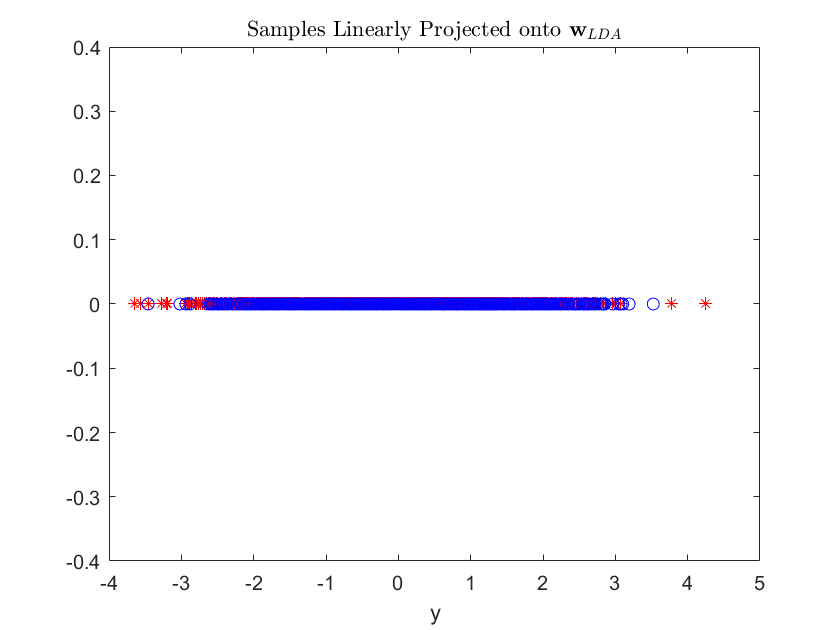

% Get sample means and covariances
mu1_hat = mean([samples([samples.label] == 1).value],2);
sigma1_hat = cov([samples([samples.label] == 1).value]');
mu0_hat = mean([samples([samples.label] == 0).value],2);
sigma0_hat = cov([samples([samples.label] == 0).value]');

% Within-class (Sw) and Between-class (Sb) scatter matrices
Sb = (mu1_hat-mu0_hat)*(mu1_hat-mu0_hat)';
Sw = sigma0_hat + sigma1_hat;

% Get eigenvalues/eigenvectors
[e_vecs, e_vals] = eig(inv(Sw)*Sb);
[~,ind] = sort(diag(e_vals),'descend');
% Get Fisher LDA project vector
w = e_vecs(:,ind(1));
y = w'*[samples.value];

y0 = w'*[samples([samples.label]==0).value];
y1 = w'*[samples([samples.label]==1).value];
plot(y0, zeros(1,sum([samples.label] == 0)),'r*'); hold on;
title('Samples Linearly Projected onto $$\mathbf{w}_{LDA}$$','interpreter','latex');
plot(y1, zeros(1,sum([samples.label] == 1)),'bo'); xlabel('y');ylim([-0.4 0.4]);
hold off;

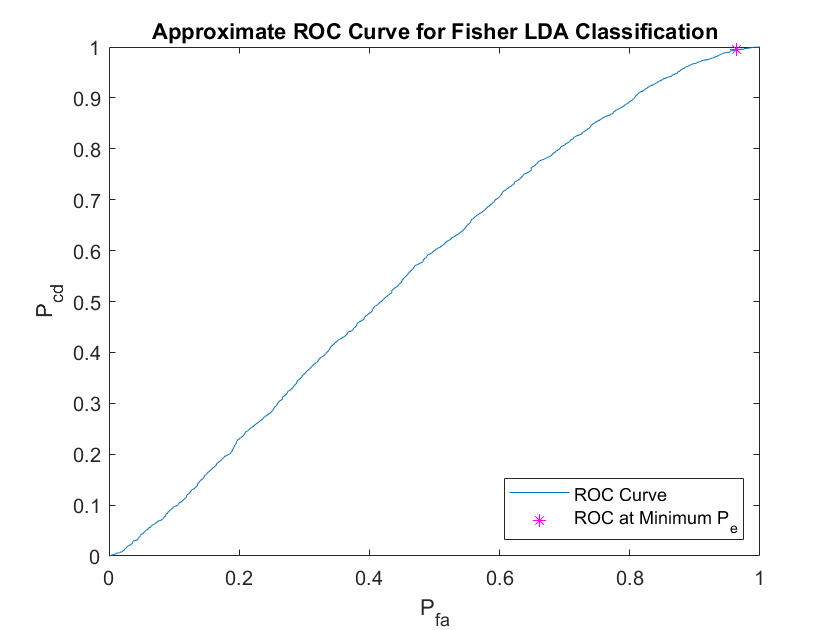

tau = -5:0.01:5;
pcd = zeros(1,length(tau));
pfa = zeros(1,length(tau));
pe = zeros(1,length(tau));
for ii = 1:length(tau)
    decision = double(y >= tau(ii));
    pcd(ii) = sum(decision == 1 & [samples.label] == 1)/sum([samples.label] == 1);
    pfa(ii) = sum(decision == 1 & [samples.label] == 0)/sum([samples.label] == 0);
    pe(ii) = sum(decision ~= [samples.label])/length(samples);
end
% Get the minimum Pe
[val,idx] = min(pe);
% ROC Curve Plot
plot(pfa,pcd); hold on;
xlabel('P_{fa}'); ylabel('P_{cd}'); title('Approximate ROC Curve for Fisher LDA Classification');
plot(pfa(idx),pcd(idx), 'm*'); hold off;
legend('ROC Curve','ROC at Minimum P_e','location','southeast');

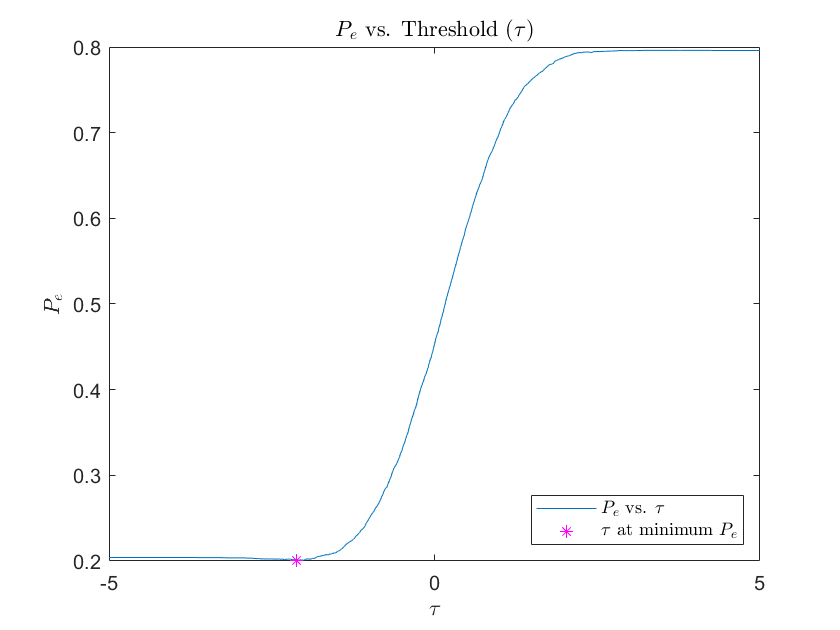

plot(tau,pe); title('$$P_e$$ vs. Threshold $$(\tau)$$','interpreter','latex'); hold on;
plot(tau(idx),pe(idx),'m*'); hold off;
ylabel('$$P_e$$','interpreter','latex'); xlabel('$$\tau$$','interpreter','latex');
legend('$$P_e$$ vs. $$\tau$$','$$\tau$$ at minimum $$P_e$$','location','southeast','interpreter','latex');

3. Threshold value for minimum probability of error, and the respective probability of error at that threshold:

fprintf(['Minimum probability of error: %f\n',...
    'Tau (threshold) value: %f\nProbability of false alarm: %f \n',...
    'Probability of correct detection: %f'], val,tau(idx),pfa(idx),pcd(idx));

Minimum probability of error: 0.200900
Tau (threshold) value: -2.120000
Probability of false alarm: 0.963253 
Probability of correct detection: 0.994597

# Question 2

1. Generation of 1000 samples from Gaussian mixture, with scatter plot:

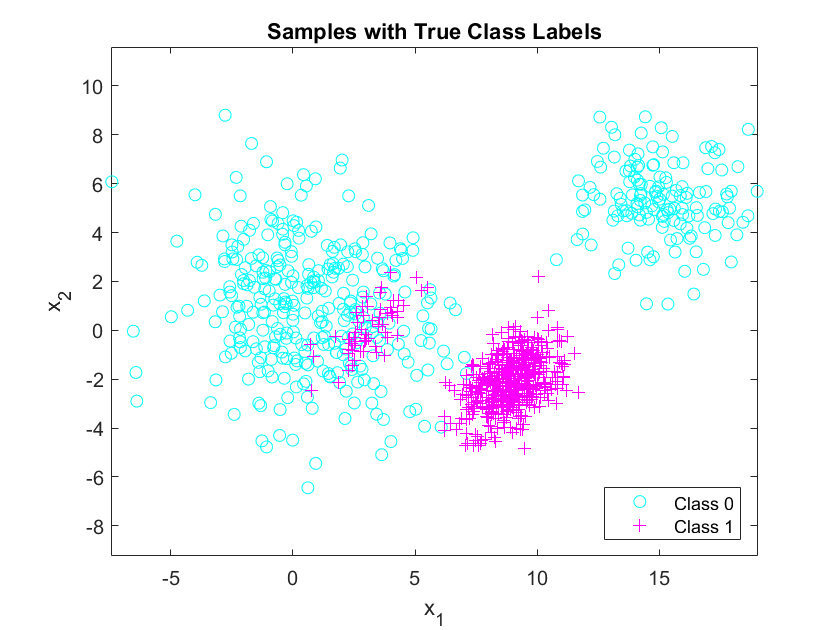

% clear vars;
n = 2;
N = 1000;
% Class 0 parameters (2 gaussians)
mu0_1 = [15;5]; mu0_2 = [1;1];
Sigma0_1 = [3 0;0 3]; Sigma0_2 = [7 -2;-2 7];
% Probability of each gaussian
p0 = [0.3 0.7];

% Class 1 parameters (2 gaussians)
mu1_1 = [9;-2]; mu1_2 = [3;0]; 
Sigma1_1 = [5 2;2 5]/5; Sigma1_2 = [9 7;7 9]/10;
% Probability of each gaussian
p1 = [0.9 0.1];

% Class priors for labels 0 and 1
p = [0.45 0.55]; 
% Decide labels for each sample
label = rand(1,N) >= p(1);
Nc = [sum(label==0) sum(label==1)];
samples = zeros(n,N); % save up space

% Draw samples from each class pdf, keeping track of where each sample
% comes from
total1 = 0; total2 = 0; total3 = 0; total4 = 0;
for i = 1:N
    if label(i) == 0
        % Class 0 samples for each gaussian based on their distribution
        distr = rand > p0(1);
        if distr == 0
            samples(:,i) = mvnrnd(mu0_1,Sigma0_1,1)';
            total1 = total1 + 1;
        else
            samples(:,i) = mvnrnd(mu0_2,Sigma0_2,1)';
            total2 = total2 + 1;
        end
    end
    
    if label(i) == 1
        % Class 1 samples for each gaussian based on their distribution
        distr = rand(1,1) > p1(1);
        if distr == 0
            samples(:,i) = mvnrnd(mu1_1,Sigma1_1,1)';
            total3 = total3 + 1;
        else
            samples(:,i) = mvnrnd(mu1_2,Sigma1_2,1)';
            total4 = total4 + 1;
        end
    end
end

% Plot with class labels
clf;
plot(samples(1,label==0),samples(2,label==0),'co'); hold on;
plot(samples(1,label==1),samples(2,label==1),'m+'); hold off; axis equal;
legend('Class 0','Class 1','location','southeast'); 
title('Samples with True Class Labels');
xlabel('x_1'); ylabel('x_2');

2. The minimum $P_e$ classification rule is $P(L=1|\mathbf{x}) {>} P(L=0|\mathbf{x}) \Longrightarrow D=1$, which can be rewritten using Bayes rule and the Gaussian mixtures for each class as: 


$$P(\mathbf{x}|L=1)P(L=1) {>} P(\mathbf{x}|L=0)P(L=0) \Longrightarrow D=1$$


$\alpha_3P(\mathbf{x}|\alpha_3, L=0)P(L=0)+\alpha_4P(\mathbf{x}|\alpha_4, L=0) P(L=0){>}
\alpha_1P(\mathbf{x}|\alpha_1, L=1)P(L=1)+\alpha_2P(\mathbf{x}|\alpha_2, L=1)P(L=1) \Longrightarrow D=1$, 

where $\alpha_i$ is the class-conditional Gaussian mixture coefficient. If we let $g_i(\mathbf{x})$be the discriminant function for the i-th class, then

$g_0(\mathbf{x}) = \alpha_1P(\mathbf{x}|\alpha_1, L=1)P(L=1)+\alpha_2P(\mathbf{x}|\alpha_2, L=1)P(L=1)
\\
g_1(\mathbf{x}) = \alpha_3P(\mathbf{x}|\alpha_3, L=0)P(L=0)+\alpha_4P(\mathbf{x}|\alpha_4, L=0) P(L=0) $ , 

and the decision rule becomes: $g_1(\mathbf{x}) - g_0(\mathbf{x}){>} 0
\Longrightarrow D=1$.

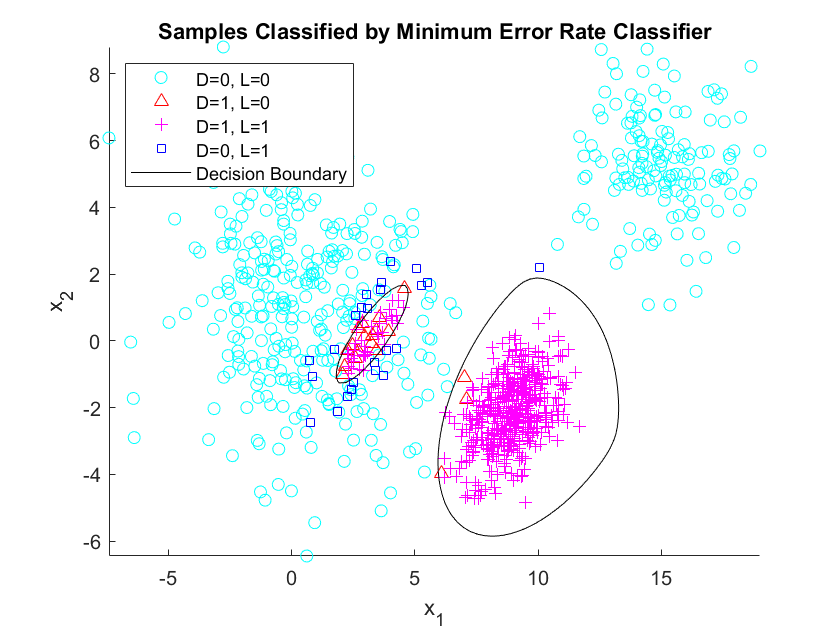

g1 = p1(1)*evalGaussian(samples,mu1_1,Sigma1_1) + p1(2)*evalGaussian(samples,mu1_2,Sigma1_2);
g0 = p0(1)*evalGaussian(samples,mu0_1,Sigma0_1) + p0(2)*evalGaussian(samples,mu0_2,Sigma0_2);
decision = double(g1 - g0 >= 0);
idx00 = decision == 0 & label == 0;
idx01 = decision == 0 & label == 1;
idx10 = decision == 1 & label == 0;
idx11 = decision == 1 & label == 1;

% Plot classifier decisions
figure; hold on;
plot(samples(1,idx00),samples(2,idx00),'oc'); 
plot(samples(1,idx10),samples(2,idx10),'^r');
plot(samples(1,idx11),samples(2,idx11),'+m');
plot(samples(1,idx01),samples(2,idx01),'sb');
% xlim([-50 50]); ylim([-50 50]);
xlabel('x_1'); ylabel('x_2');
xlabel('x_1');ylabel('x_2');title('Samples Classified by Minimum Error Rate Classifier');

% Add decision boundary
h_grid = linspace(min(samples(1,:)),max(samples(1,:)),100);
v_grid = linspace(min(samples(2,:)),max(samples(2,:)),100);
[h,v] = meshgrid(h_grid,v_grid);
class1_values = p1(1)*evalGaussian([h(:)';v(:)'],mu1_1,Sigma1_1)+ p1(2)*evalGaussian([h(:)';v(:)'],mu1_2,Sigma1_2);
class0_values = p0(1)*evalGaussian([h(:)';v(:)'],mu0_1,Sigma0_1)+ p0(2)*evalGaussian([h(:)';v(:)'],mu0_2,Sigma0_2);
discriminant_scores = log(class1_values) - log(class0_values);
discriminant_scores = reshape(discriminant_scores,100,100);
contour(h_grid,v_grid,discriminant_scores,[0 0],'k');
legend('D=0, L=0','D=1, L=0','D=1, L=1','D=0, L=1','Decision Boundary','location','northwest');
hold off;

Pe = (sum(idx01) + sum(idx10))/N;
fprintf('Minimum probability of error achievable, using minimum error rate classifier: %f', Pe);

Minimum probability of error achievable, using minimum error rate classifier: 0.043000

# Question 3

The classification rule that minimizes probability of error is the MAP decision rule: $p(L=1|\mathbf{x}) > p(L=0|\mathbf{x}) \Longrightarrow D = 1$. Using Bayes rule,

$p(\mathbf{x}|L=1)p(L=1) > p(\mathbf{x}|L=0)p(L=0) \Longrightarrow D = 1$, since the class prior are equal, this is equivalent to $p(\mathbf{x}|L=1)> p(\mathbf{x}|L=0)\Longrightarrow D = 1$. The decision boundary occurs where $p(\mathbf{x}|L=1) - p(\mathbf{x}|L=0)=0$, where $p(\mathbf{x}|L=0) = \frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x+2)^2$and $p(\mathbf{x}|L=1) = \frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x-2)^2$.

To find the decision boundary, 


$$\frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x+2)^2} = \frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x-2)^2}\\
ln(\frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x+2)^2}) - ln(\frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x-2)^2}) = 0\\
ln(\frac{e^{-\frac{1}{2}(x+2)^2}}{e^{-\frac{1}{2}(x-2)^2}})=ln(e^{-\frac{1}{2}(x+2)^2+\frac{1}{2}(x-2)^2})=
-\frac{1}{2}(x+2)^2+\frac{1}{2}(x-2)^2=0
$$


Therefore, the two Gaussian pdfs intersect at $x=0$.

The probability of error can be written as: $P_e = \int_{R_1}p(\mathbf{x}|L=0)p(L=0)dx+
 \int_{R_0}p(\mathbf{x}|L=1)p(L=0)dx$, where $R_i$ is the decision region for the i-th class. Using the decision boundaries: $R_0: (-\infty,0), R_1:[0,\infty)$, class priors, and class-conditional pdfs of this problem, 


$$P_e = \int_0^\infty p(\mathbf{x}|L=0)p(L=0)dx+
 \int_{-\infty}^0 p(\mathbf{x}|L=1)p(L=1)dx=
0.5 \int_0^\infty \frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x+2)^2}dx + 0.5 \int_{-\infty}^0\frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(x-2)^2}dx$$

$$$$


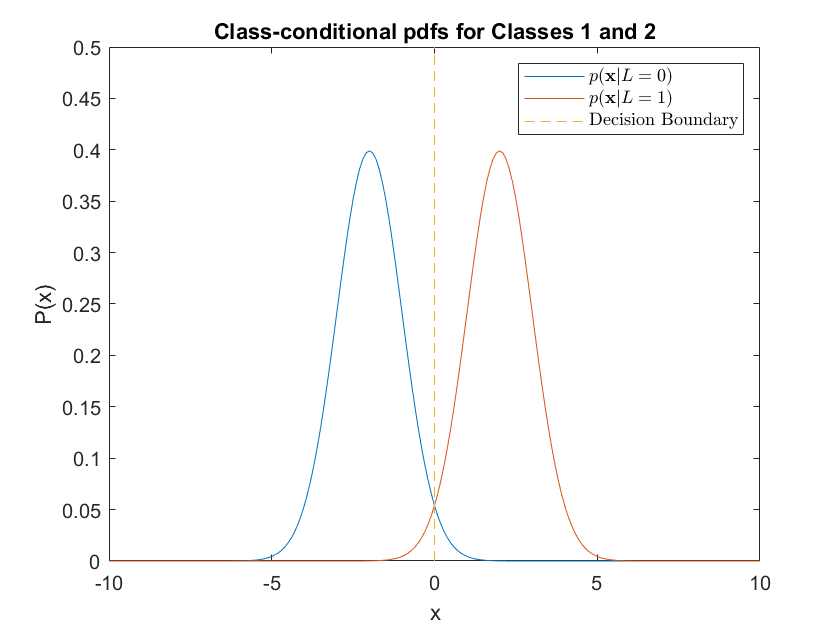

% Create both classes as structs
class0.label = 0;
class0.prior = 0.5;
class0.mu = -2;
class0.sigma = 1;

class1.label = 1;
class1.prior = 0.5;
class1.mu = 2;
class1.sigma = 1;

samples = struct();
% Create data labels
labels = rand(1,10000);
% Assign pdfs to samples, given labels
for ii = 1:length(labels)
    if labels(ii) >= class0.prior
        samples(ii).value = normrnd(class0.mu, class0.sigma);
        samples(ii).label = 0;
    else
        samples(ii).value = normrnd(class1.mu, class1.sigma);
        samples(ii).label = 1;
    end
end

likelihood0 = evalGaussian([samples.value],class0.mu,class0.sigma);
likelihood1 = evalGaussian([samples.value],class1.mu,class1.sigma);
lrt = likelihood1 - likelihood0;
decision = double(lrt >= 0);

x = -10:0.1:10;
pdf0 = (1/sqrt(2*pi)).*exp((-1/2).*(x-class0.mu).^2);
pdf1 = (1/sqrt(2*pi)).*exp((-1/2).*(x-class1.mu).^2.);
clf; plot(x,pdf0); hold on; 
plot(x,pdf1); 
plot(zeros(1,2), [0 0.5],'--');
xlabel('x'); ylabel('P(x)');
title('Class-conditional pdfs for Classes 1 and 2');
legend('$$p(\mathbf{x}|L=0)$$','$$p(\mathbf{x}|L=1)$$','Decision Boundary','interpreter','latex');
hold off;

% Get Pe from sample classifications
pe = sum(decision ~= [samples.label])/length(samples);
% Get Pe from definite integrals
pe_calc = 0.5*qfunc(2) + 0.5*(1-qfunc(-2));
fprintf('P(error) estimated from samples: %f\nP(error) from class-conditional pdf integration: %f', pe, pe_calc);

P(error) estimated from samples: 0.021800
P(error) from class-conditional pdf integration: 0.022750